plot the ecg signal

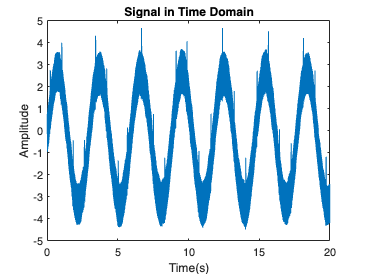

load('ecg.mat');

fs = 360; %Hz
t=linspace(0,length(ecg)/fs,length(ecg));
figure()
plot(t,ecg);
title('Signal in Time Domain');
xlabel('Time(s)');
ylabel('Amplitude');


figure()
f=linspace(-fs/2,fs/2,length(ecg));
fft_ecg = fftshift(abs(fft(ecg))) % FFT of ECG signal

fft_ecg = 1.0e+04 *

    0.0002
    0.0002
    0.0002
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0001
    0.0002


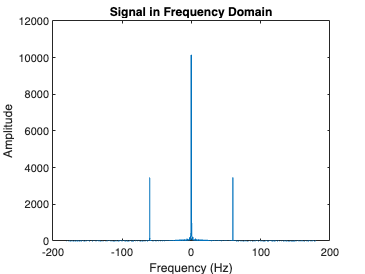


plot(f,fft_ecg);
title('Signal in Frequency Domain'); 
xlabel('Frequency (Hz)');
ylabel('Amplitude');

dallo spettro del segnale si nota un picco a +-60 Hz, potrebbe essere un artefatto da strumentazione.

si può rimuovere con un filtro IIR stop-band centrato in 60 Hz.

plotto adesso ecg1

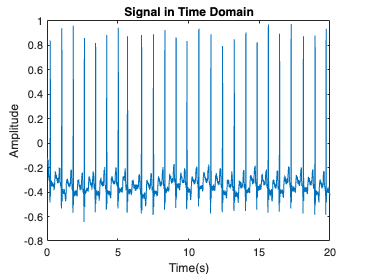

load('ecg1.mat');

fs = 360; %Hz
t=linspace(0,length(ecg1)/fs,length(ecg1));
figure()
plot(t,ecg1);
title('Signal in Time Domain');
xlabel('Time(s)');
ylabel('Amplitude');


figure()
f=linspace(-fs/2,fs/2,length(ecg1));
fft_ecg1 = fftshift(abs(fft(ecg1)))

fft_ecg1 = 1.0e+03 *

    0.0030
    0.0011
    0.0010
    0.0006
    0.0008
    0.0004
    0.0002
    0.0005
    0.0003
    0.0008


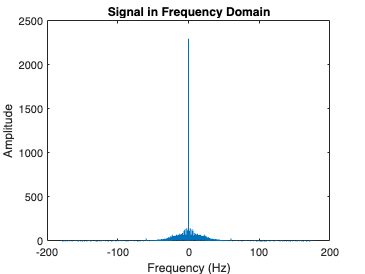


plot(f,fft_ecg1);
title('Signal in Frequency Domain'); 
xlabel('Frequency (Hz)');
ylabel('Amplitude');

il segnale presenta di nuovo dei picchi a  +-60 Hz. in più e visibile una baseline wander.

Generate the artefacts and sum them to the original signals:

% powerline = pl
A_pl = 1;
f_pl = 60;
pl = A_pl*sin(2*pi*f_pl*t);

% baseline = bl
A_bl = 0.8;
f_bl = 0.3;
bl = A_bl*sin(2*pi*f_bl*t);

% ecg with artifacts
ecg_sum = ecg1 + pl' + bl';

Use the function add_noise.m to add white gaussian noise to the signals, with a SNR = 20dB.

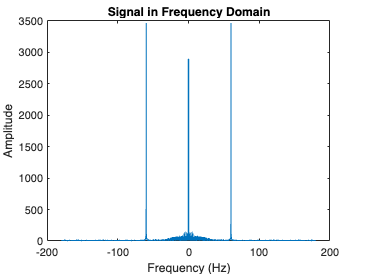

SNR = 20; %dB
ecg_sum_noise = addNoise(ecg_sum, t, SNR);
fft_ecg_sum_noise = fftshift(abs(fft(ecg_sum_noise)));

% figure()
% plot(t,ecg_sum_noise);
% title('Signal in Time Domain');
% xlabel('Time(s)'); 
% ylabel('Amplitude');

figure()
plot(f,fft_ecg_sum_noise);
title('Signal in Frequency Domain'); 
xlabel('Frequency (Hz)');
ylabel('Amplitude');